% 1D XRD Analysis
% (XRD of very thin wire)

% Unit cell info
a = 4.1; % in Angstrom
a = a*10^-10;

atomPositions = [0];

% X-Ray beam 
beamkeV = 8.05; %Enter value in keV
lambda = (H*C)/(beamkeV*(6.2415096471204*10^15)^-1); % m

% XRD
planesMaterial = [];
thetaMaterial = [];
intensity = [];
F = [];
dspace = [];
for h = 1:10
    d = dspacing1(h,a);
    
    if lambda/(2*d) <= 1 && lambda/(2*d) >= -1  
        theta = asind(lambda/(2*d));

        atoms = zeros(size(atomPositions,2),1);
        for i1 = 1:length(atoms)
            atoms(i1) = exp(2*pi*1i*(h*atomPositions(i1)));
        end
        f = abs(real(sum(atoms)));
        if f == 0
            continue;
        end
        
        dspace = [dspace; d];
        F = [F; sum(atoms)*formFactor(4*pi*sind(theta)/(lambda*10^10))];
        planesMaterial = [planesMaterial; h];
        thetaMaterial = [thetaMaterial; theta];
        intensity = [intensity; abs(F(end))^2];
    end
end

data = [planesMaterial,2*thetaMaterial,dspace*10^10,intensity];
array2table(data,"VariableNames",{'h', '2theta [º]','dspace [A]', 'Intensity'})

ans = 5×4 table
    h    2theta [º]    dspace [A]    Intensity
    _    __________    __________    _________

    1      21.652           4.1       895.79  
    2      44.129          2.05       649.79  
    3      68.594        1.3667       448.48  
    4      97.407         1.025       309.12  
    5      139.81          0.82       222.13  


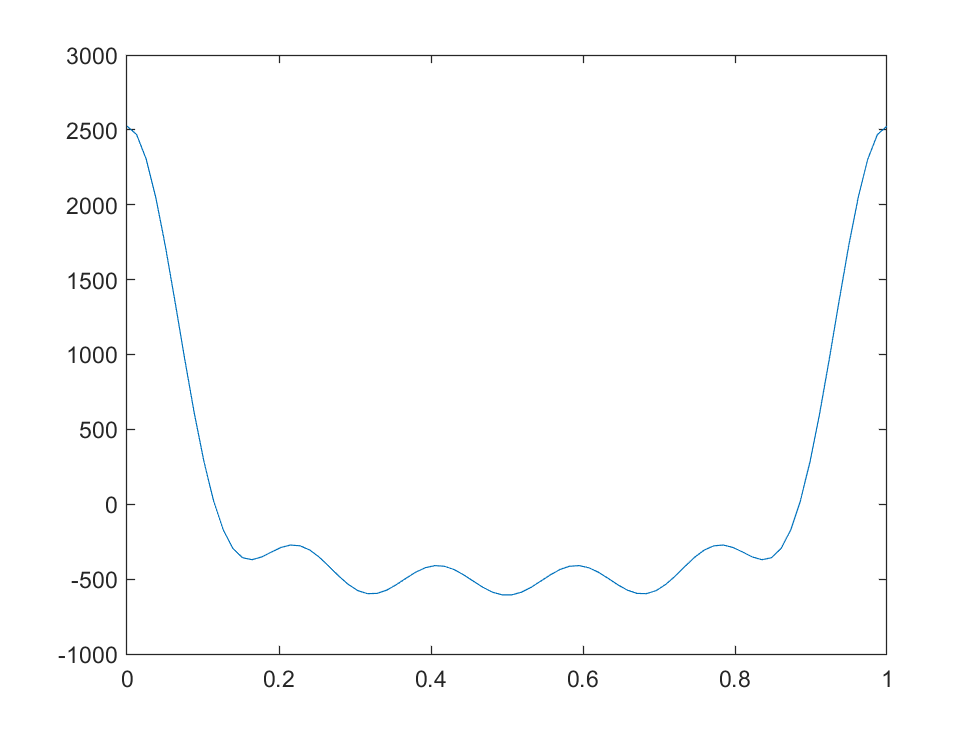

points = 80;

positions = ones([1 points]).*linspace(0,1,points);
P = zeros(points,1);
for u = 1:points
    for plane = 1:length(planesMaterial)
        P(u) = P(u) + ...
            abs(F(plane))^2*...
            exp(-2*pi*1i*planesMaterial(plane)*positions(u));
    end
end

plot(positions,real(P))

function spacing = dspacing1(h1,a)
    spacing = sqrt((h1^2/a^2)^-1);
end

function f = formFactor(g)
    f = 0;
    ax = [13.338 7.1676 5.6158 1.6735]; %Data for Cu
    bx = [3.5828 0.247 11.3966 64.8126];
    cx = 1.191;
    for idx = 1:4
        f = f + ax(idx)*exp(-bx(idx)*(g/(4*pi))^2)+cx;
    end
end